# Unit 4.3: Fourier Transforms for Circuit and LTI Analysis

Prepared for EG-247 Digital Signal Processing by Dr C.P. Jobling

## Example 2

Karris example 8.9: for the circuit shown below, use the Fourier transfrom method, and the system function $H(\omega)$ to compute $v_L(t)$. Assume $i_L(0^-)=0$. Verify the result with MATLAB.

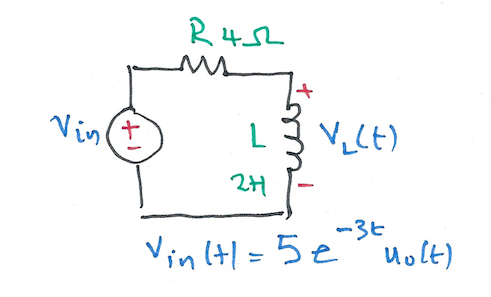

Worked solution: [ft3_ex2.pdf](https://cpjobling.github.io/eg-247-textbook/fourier_transform/solutions/ft3-ex2.pdf).

syms t w
H = j*w/(j*w + 2)

Vin = fourier(5*exp(-3*t)*heaviside(t),t,w)

Vout=simplify(H*Vin)

vout = simplify(ifourier(Vout,w,t))

### Plot result

fplot(vout,[0,5])
title('Solution to Example 2')
ylabel('v_{out}(t) [V]')
xlabel('t [s]')
grid